# Least Squares Support Vector Machines, Ex. 1

First set up the environment and load the LSSVM KU Leuven package.

rng(666)

## Two Gaussians

Two Gaussians with the same covariance matrix generate a dataset. Can we manually create something resembling an optimal classifier?

[X1, X2, Y1, Y2] = deal(randn(50, 2) + 1,  randn(51, 2) - 1, ones(50, 1), -ones(51, 1));
figure; hold on; plot(X1(:,1),X1(:,2), 'ro');  plot(X2(:,1),X2(:,2), 'bo'); hold off;

For binary classification, an optimal linear classifier classifies all of the data points correctly while being as far away from the points as possible. In this case, the data are not linearly separable, hence the first condition cannot be fulfilled. The linear classifier will have some inherent misclassification rate. The far-away-ness criterion is fulfilled by maximizing a margin around the line in which no points are present.

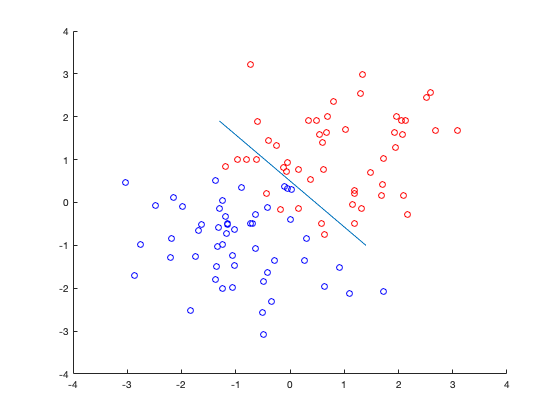

line([-1.3, 1.4], [1.9, -1])

## Support vector machine classifier

## Least-squares support vector machine classifier

Load the iris dataset into Xtrain, Xtest, Ytrain, Ytest variables.

load iris.mat

### Influence of hyperparameters and kernel parameters

We can attempt modelling with polynomial kernels of different degrees, with $t=gam=1$.

gam = 1; type = 'classification';
params = {{Xtrain, Ytrain, 'c', 1, [1 1], 'poly_kernel'}
    {Xtrain, Ytrain, 'c', 1, [1 2], 'poly_kernel'}
    {Xtrain, Ytrain, 'c', 1, [1 3], 'poly_kernel'}
    {Xtrain, Ytrain, 'c', 1, [1 4], 'poly_kernel'}
    {Xtrain, Ytrain, 'c', 1, [1 5], 'poly_kernel'}}

params = 5×1 cell array
    {1×6 cell}
    {1×6 cell}
    {1×6 cell}
    {1×6 cell}
    {1×6 cell}


polModels = arrayfun(@(x) trainlssvm(x{1}), params)

polModels = 5×1 struct array with fields:
    type
    x_dim
    y_dim
    nb_data
    kernel_type
    preprocess
    prestatus
    xtrain
    ytrain
    selector
    gam
    kernel_pars
    x_delays
    y_delays
    steps
    latent
    code
    codetype
    pre_xscheme
    pre_yscheme
    pre_xmean
    pre_xstd
    pre_ymean
    pre_ystd
    status
    weights
    b
    alpha
    duration
